## PROBLEM 3.0

%{
ES 115 CLASS PROJECT PROBLEM 3.0
PROBLEM TITLE: Water tank fill and drain (piecewise linear)
DESCRIPTION: This program models the volume of a water tank over a 25v
minute period time. The tank fills for the first 10 minutes and drains for
the remaining 15 minutes.
PURPOSE: To simulate piecewise continuous functions and identify the intersection point(maximum volume) of two different flow rates 
INPUTS: 
    ~ t - Time vector from 0 to 25 minutes
    ~ Fill Rate - 5L/min (from t = 0 to 10)
    ~ Drain Rate - 3L/min (from t = 10 to 25)
    ~ V0 - Initial volume of 20L
OUTPUTS:
    ~ V - Volume of the water tank at each time step (L)
    ~ V_max - The peak volume reached at the 10-minute mark
ENGINNERING ALGORITHMS:
- Define a time vector for the full duration (0-25 min)
- Implement a piecewise logic:
    Phase 1 (0 <= t <= 10): V = 5t + 20
    Phase 2 (10 <= t <= 25): V = -3(t - 10) + 70
- Identify the intersection point where the phases meet
- Calculate the final volume remaining in the tank
MATLAB TOOLS/FUNCTIONS:
- Loops/logical indexing
- Vector initialization
- Relational operations
- 2D plotting
%}

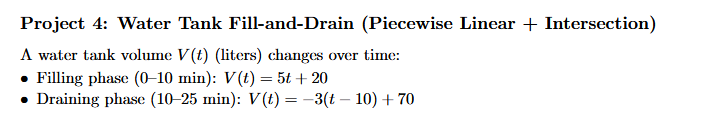

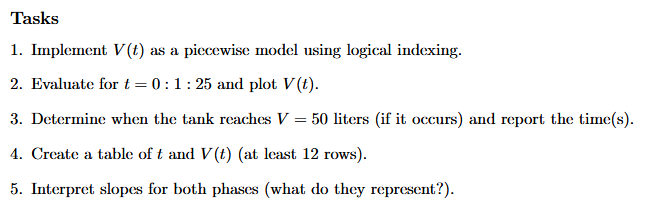

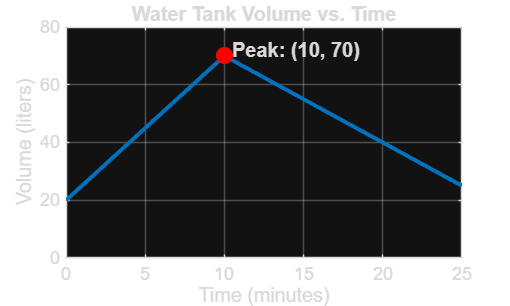

% Initialize workspace and figure state
clc; clear; close all
t = 0:0.1:25;
V = zeros(size(t));
% Compute piecewise volume over time: filling then draining
% Loop over time samples in t
for i = 1:length(t)
    % Check if current time is within the 0–10 window (inclusive)
    if t(i) >= 0 && t(i) <= 10
        % Filling phase: V(t) = 5t + 20
        % Compute V for early time segment (affine relation)
        V(i) = 5*t(i) + 20;
    elseif t(i) > 10 && t(i) <= 25
        % Draining phase: V(t) = -3(t - 10) + 70
        V(i) = -3*(t(i) - 10) + 70;
    end
end
% Create white-background figure for plotting
figure('Color', 'w');
% Plot voltage vs time with thicker blue line
plot(t, V, 'LineWidth', 2, 'Color', [0 0.4470 0.7410]);
% Enable grid for readability
grid on;
% Hold to overlay additional plots
hold on;
% Plot a highlighted peak point on the volume-time figure
plot(10, 70, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
% Label the peak value near the marker
text(10.5, 72, 'Peak: (10, 70)', 'FontSize', 10, 'FontWeight', 'bold');
% Add figure labels and limits
title('Water Tank Volume vs. Time');
xlabel('Time (minutes)');
ylabel('Volume (liters)');
axis([0 25 0 80]);

% Report volumes at selected times
fprintf('Volume at t=0:  %.1f L\n', V(t == 0));

Volume at t=0:  20.0 L


fprintf('Volume at t=10: %.1f L (Max)\n', V(t == 10));

Volume at t=10: 70.0 L (Max)


fprintf('Volume at t=25: %.1f L\n', V(t == 25));

Volume at t=25: 25.0 L
